# Phonon Visualization for MATLAB

Visualize Quantum ESPRESSO crystal structures and phonon modes.

## Classes

## Display Multiple Structures Using tiledlayout

Stuctures are from [https://next-gen.materialsproject.org/](https://next-gen.materialsproject.org/)

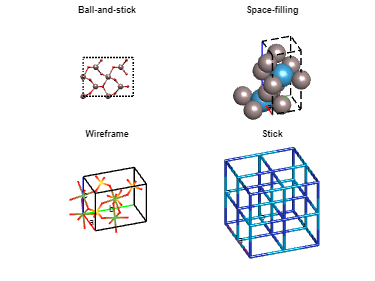

Processing file: examples\tiledlayout\Ga2O3.poscar
Processing file: examples\tiledlayout\HfAl3.poscar
Processing file: examples\tiledlayout\NiSO4.poscar
Processing file: examples\tiledlayout\ThN.poscar


VPHMAT.setBondLength('Ga','O',2.2)
VPHMAT.setBondLength('Ni','O',2.1)
VPHMAT.setBondLength('N','Th',2.6) % set once and for all

figure
t=tiledlayout(2,2);
t.TileSpacing='none';
t.Padding='compact';

folder = 'examples/tiledlayout';
files = dir(fullfile(folder, '*.poscar'));
for k = 1:length(files)
    filename = fullfile(folder, files(k).name);
    disp(['Processing file: ', filename]);
    qe = QE.fromPOSCAR(filename);
    v = VPHMAT(qe);
    nexttile
    switch k
        case 1
            v.style='Ball-and-stick';
            v.view='a';
            v.general.unitCell.lineStyle=':';
            v.general.axes.showCompass=false;
            v.general.axes.showAxisLabels=false;
            v.boundary='none';
            title('Ball-and-stick')
        case 2
            v.style='Space-filling';
            v.general.unitCell.lineStyle='--';
            title('Space-filling')
        case 3
            v.style='Wireframe';
            title('Wireframe')
        case 4
            v.style='Stick';
            v.boundary='A1';
            title('Stick')
    end
    v.plot();
    switch k
        case 1
            v.view='a';
    end
end

## Interactive phonon visualizer

Operations are quite similar to [Interactive phonon visualizer](https://interactivephonon.materialscloud.io/), but here we use prefix.xml and matdyn.modes instead of scf.in, scf.out and matdyn.modes.

Do not run this code below in LIVE SCRIPT EDITOR, run this code in normal SCRIPT file!

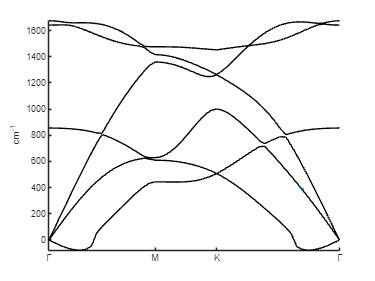

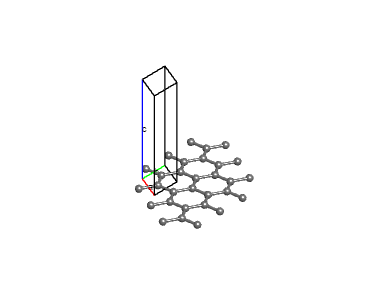

VPHMAT.setBondLength('C','C',2.1)

folder = 'examples/graphene/';
qe=QE.fromXML([folder 'graphene.xml']);
matdyn=MATDYN([folder 'matdyn.modes']);
matdyn.klabels={"\Gamma","M","K","\Gamma"};
v=VPHMAT(qe);
v.matdyn=matdyn;
v.supercell=[3 3 1];
v.phonon.amplitude=0.5;
v.phonon.speed=1;
% v.phonon.save='gif'; % or 'mp4'
figure
v.animate

## Customize plot style

Based on MATLAB, the VPHMAT package offers flexible plotting capabilities, allowing users to freely modify the appearance of atoms and valence bonds, as well as adjust the background.

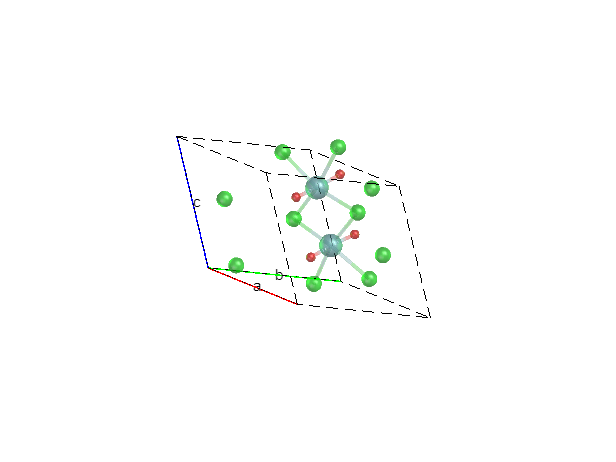

figure
filename='examples/NbOCl2/POSCAR';
qe=QE.fromPOSCAR(filename);
v=VPHMAT(qe);
v.general.unitCell.lineStyle='--';
v.plot
for i=1:v.atoms.nat
    v.hatom(i).FaceAlpha=0.5;
end
for i=1:size(v.bonds.formed,1)
    v.hbond(i,1).FaceAlpha=0.2;
    v.hbond(i,2).FaceAlpha=0.2;
end
v.view=[50 20];

lt2 = light;
lt2.Color = "g";
lt2.Style='local';
lt2.Position=[-1 0 1];